Marion Gilson, 30/01/2022

Cours Apprentissage de systèmes dynamiques, 4A IA2R apprentissage.

Ce TD vous permet d'apprendre les différentes étapes nécessaires à l'identification d'un système à partir de données réelles mesurées. On utilisera pour ce faire les données de dryer2 de Matlab. Toutes les étapes peuvent être utilisées ensuite avec d'autres données mesurées.

## I. Données

On commence par séparer les données qui vont nous servir à l'estimation et celles utilisées pour la validation des modèles (validation dite croisée).

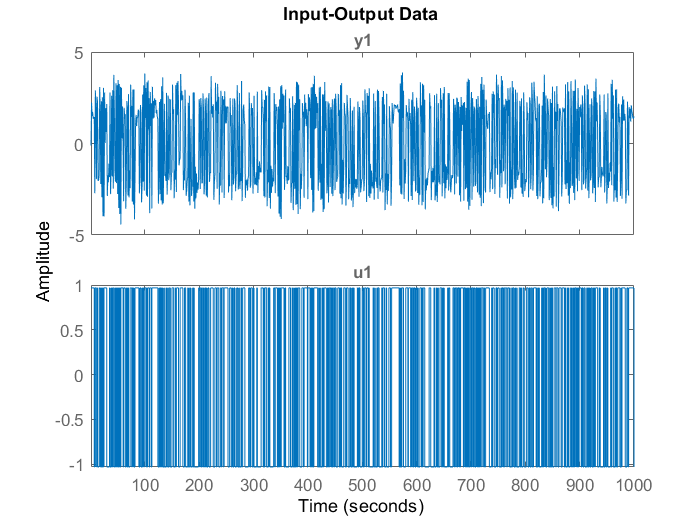

clear
close all

load simul5.mat
data=iddata(y(1:1000),u(1:1000),Ts); % pour l'estimation
dataV=iddata(y(1001:end),u(1001:end),Ts); %pour validation
%il faut couper au bon endroit

% Prétraitement des données (on enlève la moyenne, ici pas de
% dérive)(dérive = croissance continue jusque hors champ graphique)
data=detrend(data,0);
dataV=detrend(dataV,0);
idplot(data)

## II. Estimations initiales

Avant de se lancer dans une estimation d'un modèle de type boîte noire, il faut acquérir des connaissances sur le système. Plusieurs étapes sont nécessaires.

### II.1 Estimation de la réponse fréquentielle

La réponse fréquentielle et la réponse impulsionnelle sont des modèles non paramétriques qui permettent d'aider à la compréhension des principales caractéristiques du système à identifier. Ces modèles ne sont pas représentés par une formule mathématique, mais plutôt à l'aide de représentation graphique.

La toolbox System Identification de Matlab comporte 3 fonctions pour estimer la réponse fréquentielle :

- etfe calcule la fonction de transfert empirique en utilisant l'analyse de Fourier ;

- spa estime la fonction de transfert à partir de l'analyse spectrale, pour une résolution de fréquence fixée ;

- spafdr permet de choisir la fréquence de résolution d'intérêt pour estimer la réponse fréquentielle.

On propose ici d'utilise la fonction spa.

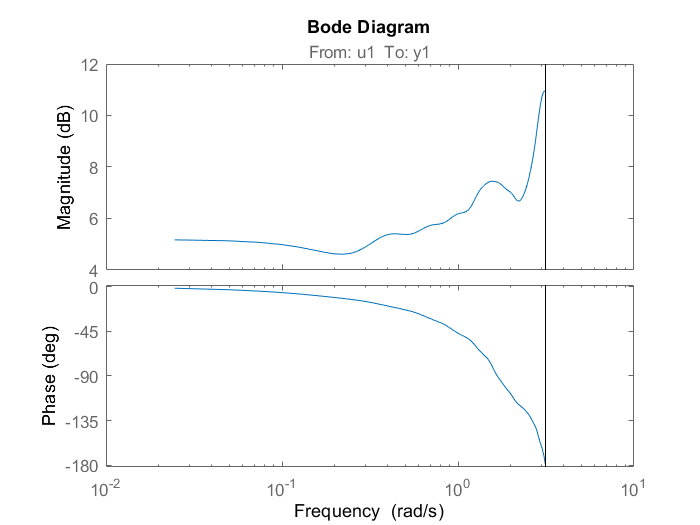

Ge=spa(data);%spa est la plus simple à utiliser, c'est une analyse spectrale
%Représentation de la réponse fréquentielle par un diagramme de Bode
bode(Ge)


%le bode ne décroit pas, c'est un deuxième ordre ou plus
%on constate un retard entre la sortie et l'entrée

% hypothese : ordre 4 (tout de meme phase etrange)



%le bode est correct, il n'y a pas de resonnace donc pas de pole complexe
%conjugué donc ok. ça peut être un premier ordre ou deuxième ordre
%périodique. un ordre 4 descendrait bcp pus rapidement

%si le diagramme de phase descend rapident c'est qu'il y a un retard entre la sortie et l'entrée

On remarque ici qu'il n'y a pas de pic de résonnance et que la descente a une pente qui se situe entre -20 et -40dB/decade.

On voit également que la phase descend rapidement, ce qui peut peut-être suggérer un retard entre la sortie et l'entrée.

### II.2 Estimation de la réponse indicielle empirique

Pour estimer la réponse indicielle à partir des données, il faut tout d'abord estimer un modèle FIR (Finite Impulse Response) à partir des données puis représenter sur une figure sa réponse indicielle.

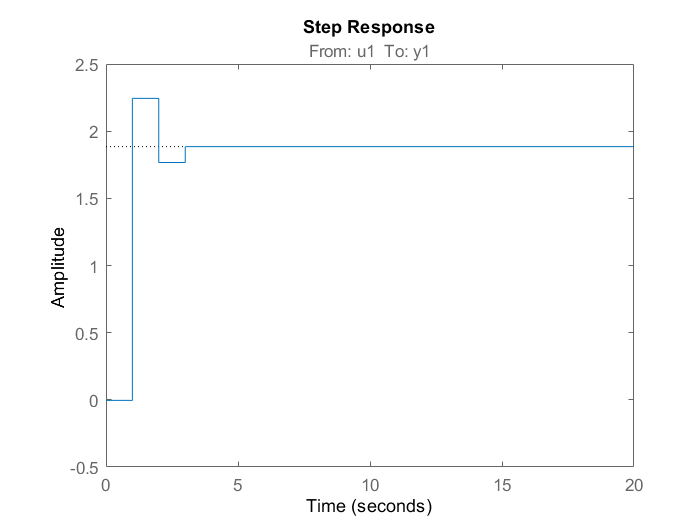

% Estimation du modèsle de réponse impulsionelle
Mimp=impulseest(data,4);%on ne peut pas modéliser car un ordre 60 est inutile
%pas de dépassement donc 1er/2eme ordre et pas de pole complexe conjugué
%le retard est modéliser par le petit temps au début. ici on peut estimer
%le retard et c'est l'objectif (à prendre avec des pincettes)

%réponse indicielle
step(Mimp)




%Dans ce cas on a un dépassement donc on peut confirmer le retard entre
%l'entre et la sortie ET que ce n'est pas un 1er ordre, un seul dépassement
%donc c'est un deuxème ordre

On remarque qu'il n'y a pas de dépassement, ce qui indique qu'il s'agit soit d'un système du 1er ordre, soit d'un système d'ordre supérieur mais à pôles réels.

On note aussi un retard sur le système, ce qui confirme la descente rapide sur la phase du Bode. Il nous faut donc estimer ce retard.

### II.3 Estimation du retard

Il est important d'avoir une estimation du retard pour pouvoir utiliser cette connaissance ensuite lors de l'estimation de modèle boîte noire de type arx, ou autre.

Cette valeur peut être directement lue sur la réponse indicielle ou (mieux) estimée grâce à la commande delayest.

delayest(data)%estimation du retard (en nombre d'échantillon)

ans = 1

Le retard estimé est donc de 3 échantillons. Vérifions cette estimation en utilisant la réponse impulsionnelle estimée, puis représentons à l'écran l'intervalle de confinace accordée à cette estimation.

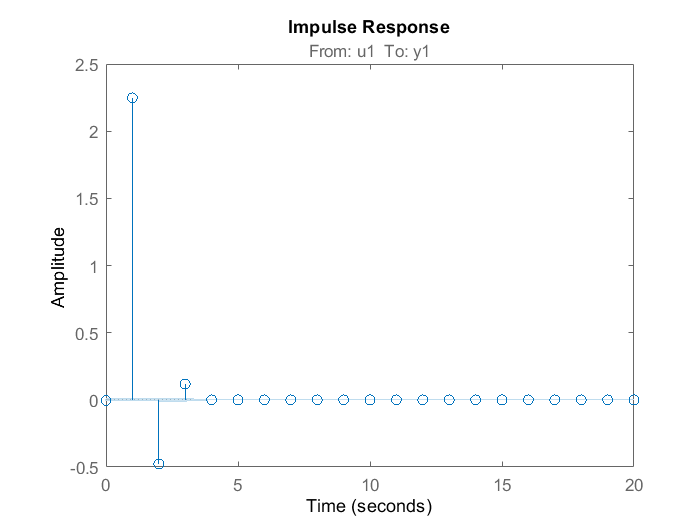

clf
h = impulseplot(Mimp);
showConfidence(h,1)%retrouvé le retard sur le 1 premiers échantillons

### II.4 Estimation de la structure du modèle

Pour pouvoir estimer un modèle boîte noire (arx, oe ou autre), il est nécessaire de connaitre l'odre des polynômes de la fonction de transfer. Comme ils sont inconnus, nous allons, dans cette partie, utiliser 3 fonctions de Matlab pour estimer les ordres d'un modèle ARX : 

- struc crée une matrice avec les ordres de modèles sélectionnés dans un ordre spécifique : na, nb, nk ;

- arxstruc estime pour chaque ordre de modèle de struc le modèle arx correspondant et effectue une comparaison entre la sortie mesurée et la sortie issue de chaque modèle ; il retourne ensuite une fonction coût pour chaque modèle qui correspond à la somme normalisée des erreurs de prédiction au carré ;

- selstruc utilise la sortie de arxstruc et ouvre une fenêtre de sélection de modèle pour chacun. Il faut alors utiliser cette fenêtre pour sélectionner le modèle approprié. 3 critères sont proposés : best fit, critère Rissanen, critère Akaike.

D'après les études précédentes, il parait intéressant de tester les ordres suivants :

- na=2:6 ;

- nb=2:6 ;

- nk=1.

NN=struc(2:6,2:6,1);%ordre(na;nb;nk)
selstruc(arxstruc(data,dataV,NN))%affiche une fenêtre avec les barres jaunes en fonction du modèle, on a les différentes 
%valeurs d'ordre na et nb et nk. La barre la plus grande est celle où il
%reste le maximum de valeur donc à ne pas choisir. (rouge à choisir (best
%fit))
%cependant, le plus simple est souvent le mieux (ici modèle 4 ou 6)(choisir
%le minimum de paramètre
%on peut en essayer plusieurs et voir les variations

D'après la figure provenant de selstruc, plusieurs structures de modèle donnent quasiment le même résultat qui est : na=5, nb=2, nk=1.

### II.5 Estimation d'une fonction de transfert

Cette étape est facultative.

#### Estimation

Avec les dernières versions de Matlab, on peut désormais estimer une fonctoin de trasnfert à temps continu directement à partir des données. Il faut d'abord avoir préparé les données (cf plus haut) et connaître l'ordre de la FT. On utilise pour ce faire la fonction tfest.

% pour voir un rapport de progression, on utilise l'option Display
Opt=tfestOptions('Display','off');%similaire à broida

% on collecte les ordres du modèles
np=2;
ioDelay=3*Ts; % 3 échantillons en s

%estimation de la FT
mtf=tfest(data,np,[],ioDelay,Opt);
  
%pour voir les coefficients du modèle
mtf

mtf =
 
  From input "u1" to output "y1":
                -37.22 s + 2.418
  exp(-3*s) * --------------------
              s^2 + 14.17 s + 26.5
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 2.659%                   
FPE: 5.434, MSE: 5.369                           


Le modèle donne un fit de quasi 85%, ce qui parait une bonne estimation. Ces résultats doivent tout de même être confirmés par une étape de validation du modèle.

#### Validation du modèle FT

On peut comparer la sortie du modèle avec la sortie mesurée à l'aide de la fonction compare.

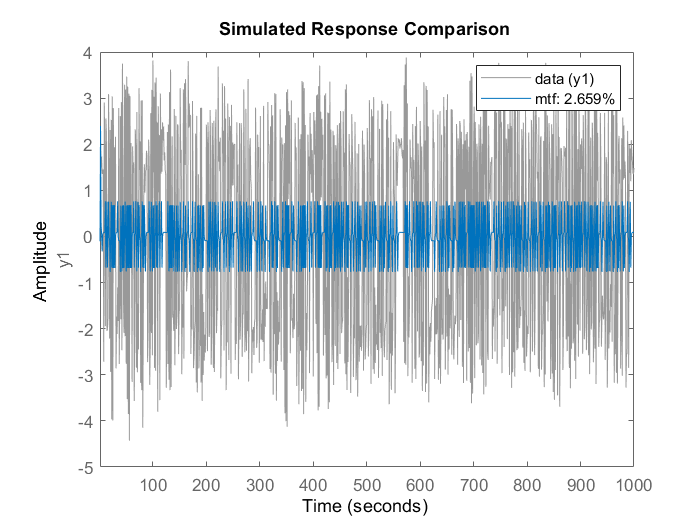

compare(data,mtf)

La comparaison montre un fit d'environ 85%. On peut ensuite analyser les résidus, à l'aide de la commande resid.

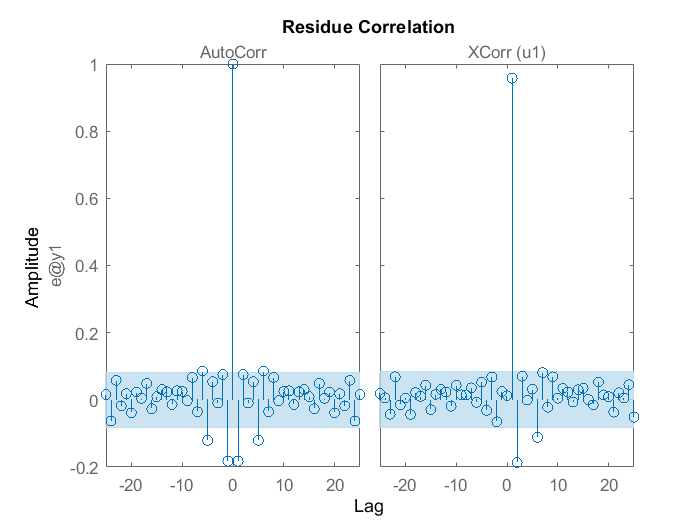

resid(data,mtf)

Les résidus montrent un haut degré d'autocorrélation, ce qui signifie que le modèle n'est pas de très bonne qualité (il reste trop d'information dans les résidus). Ceci est logique car nous n'avons pas séparé l'estimation du process de celle du bruit.

Pour ce faire, il faut utiliser les fonctions du type arx, oe, bj, iv, sriv...

## III. Estimation d'un modèle boîte noire

Nous avons appris à utiliser les fonction arx, iv4, oe, sriv pour estimer un modèle boîte noire de notre process. Nous allons les utiliser ici.

### Estimation d'un modèle arx par moindres carrés et iv4

nnarx=[5 2 1];%choisir na, nb et nk du modèle choisi
marx=arx(data,nnarx);
miv4=iv4(data,nnarx);
present(marx)

                                                                                                                                                            
marx =                                                                                                                                                      
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                         
  A(z) = 1 - 0.6522 (+/- 0.01655) z^-1 - 0.1899 (+/- 0.004233) z^-2 + 0.09354 (+/- 0.002903) z^-3 - 0.1449 (+/- 0.003081) z^-4 + 0.08101 (+/- 0.003207) z^-5
                                                                                                                                                            
  B(z) = 2.251 (+/- 0.006528) z^-1 - 1.943 (+/- 0.03766) z^-2                                                                                               
                                                          

present(miv4)

                                                                                                                                                                
miv4 =                                                                                                                                                          
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                             
                                                                                                                                                                
A(z) = 1 - 0.7849 (+/- 8.267e-05) z^-1 - 0.2183 (+/- 0.0001031) z^-2 + 0.09586 (+/- 9.421e-05) z^-3 - 0.1535 (+/- 8.563e-05) z^-4 + 0.09471 (+/- 5.424e-05) z^-5
                                                                                                                                                                
  B(z) = 2.255 (+/- 0.009021) z^-1

Estimation d'un modèle oe par oe et sriv

nnoe=[5 2 1];%choisir na, nb et nk du modèle choisi
moe=oe(data,nnoe);
msriv=sriv(data,nnoe);
present(moe)

                                                                                                                                               
moe =                                                                                                                                          
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                                                          
  B(z) = 2.243 (+/- 0.01091) z^-1 + 0.5443 (+/- 0.3196) z^-2 - 0.2856 (+/- 0.1439) z^-3 - 0.1344 (+/- 0.04187) z^-4 + 0.1374 (+/- 0.03481) z^-5
                                                                                                                                               
  F(z) = 1 + 0.4575 (+/- 0.1452) z^-1 - 0.07992 (+/- 0.09835) z^-2                                                                             
                                                                                                                                        

present(msriv)

                                                                                                                                               
msriv =                                                                                                                                        
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                                                          
  B(z) = 2.243 (+/- 0.01088) z^-1 + 0.5904 (+/- 0.2789) z^-2 - 0.2618 (+/- 0.1438) z^-3 - 0.1386 (+/- 0.03183) z^-4 + 0.1347 (+/- 0.02414) z^-5
                                                                                                                                               
  F(z) = 1 + 0.4777 (+/- 0.124) z^-1 - 0.06519 (+/- 0.08961) z^-2                                                                              
                                                                                                                                        

## IV. Comparaison des différentes méthodes d'estimation

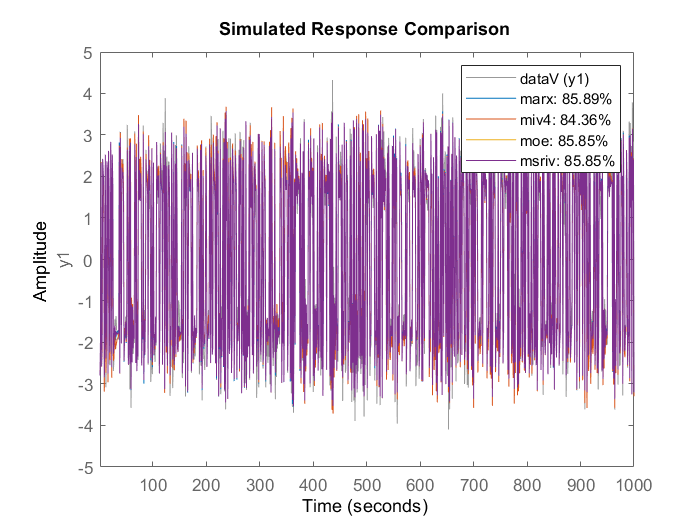

compare(dataV,marx,miv4,moe,msriv)%comparaison des data de validation avec les différentes méthodes, séparer les graphes pour plus de clarté

Toutes les méthodes donnent de bons résultats, avec un légère préférence pour oe et sriv. Analysons les résidus.

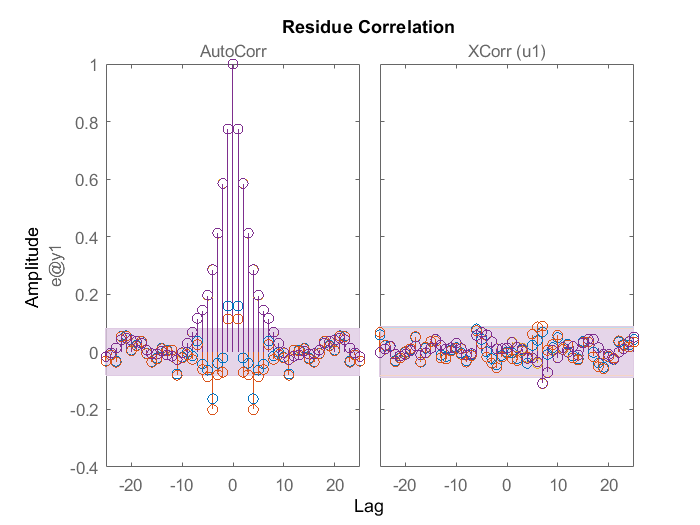

resid(dataV,marx,miv4,moe,msriv)%y - ychapeau. si c'est bien il n'y a qu'un seul grand picet la petite bande violette. si ce n'est pas cas c'est qu'il y

%y a encore bcp d'information et qu'on peut faire mieux (ici ce sont des
%perturbations pour autocorr donc on va plus loin ci-desssous)
%xcorr mieux

Bien que l'estimation semblait de bonne qualité, il reste encore des informations dans les résidus (autocorrélation trop importante). Une solution peut être trouvée en estimant un modèle de bruit différent, et plus particulièrement en estimant un modèle de type Box-Jenkins :

y=B/Fu+C/De

Comme nous n'avons pas d'information particulière sur le modèle de bruit, on prend simplement un modèle d'ordre 1 pour la fonction de transfert du bruit (pour C comme pour D).

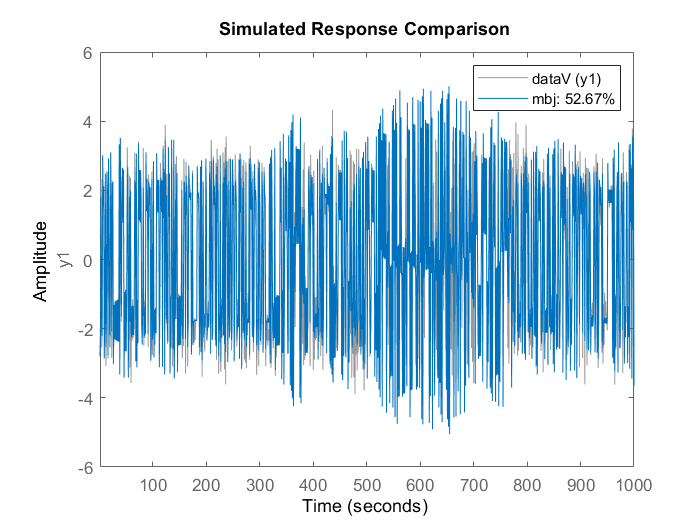

nnbj=[2 1 1 4 1];%(ordre process, bruit bruit ordre process, retard) (nb, nc, nd, nf et nk) (le pire était na=2, nb=3)
mbj=bj(data,nnbj);
compare(dataV,mbj)

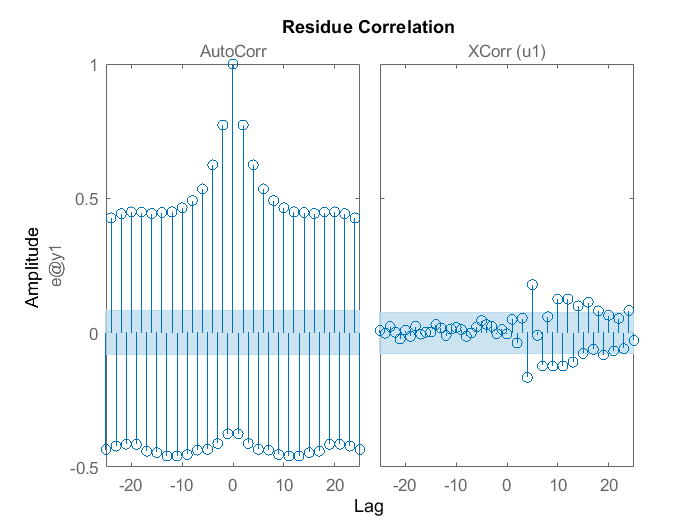

resid(dataV,mbj)% ici l'auto correlation est parfait car on a choi les bons paramètres 

L'estimation semble désormais de très bonne qualité. On comprend ainsi l'intérêt d'estimer un modèle de bruit.

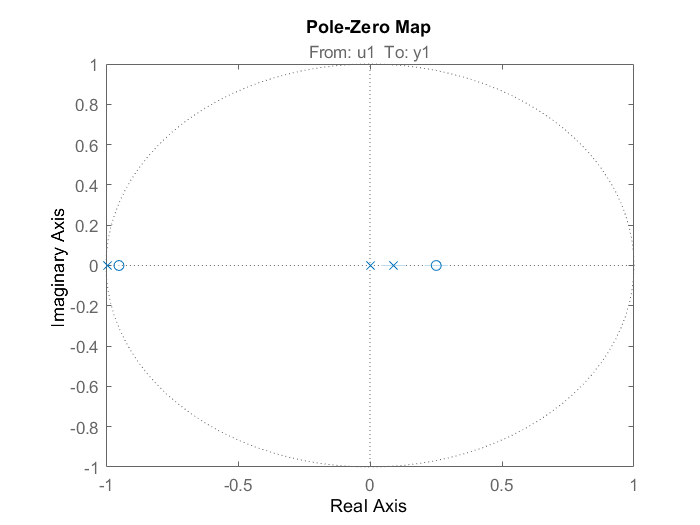

h = iopzplot(mbj);%recherche des pole et zéro
showConfidence(h,1)%les croix doivent être proche de l'abscisse et le 0 au milieu